Do the two exercises of the tutorial 2 and then answer the questions in this feedback tool.  All real numbers should be reported accurate to 4 counting digits (4 significant digits).  Arrays should be reported as strings of 3, 4 or 6 real numbers (depending on the specific answer), separated by commas and enclosed in square brackets, for example:

[2.3452, 0.0023563, 1.0000]

You need to fill in both column and row vectors as a string of numbers, as shown above.

Please note: If you do not strictly follow these  instructions you will loose marks.

This assignment is due at 23:59 on April 13, 2026.

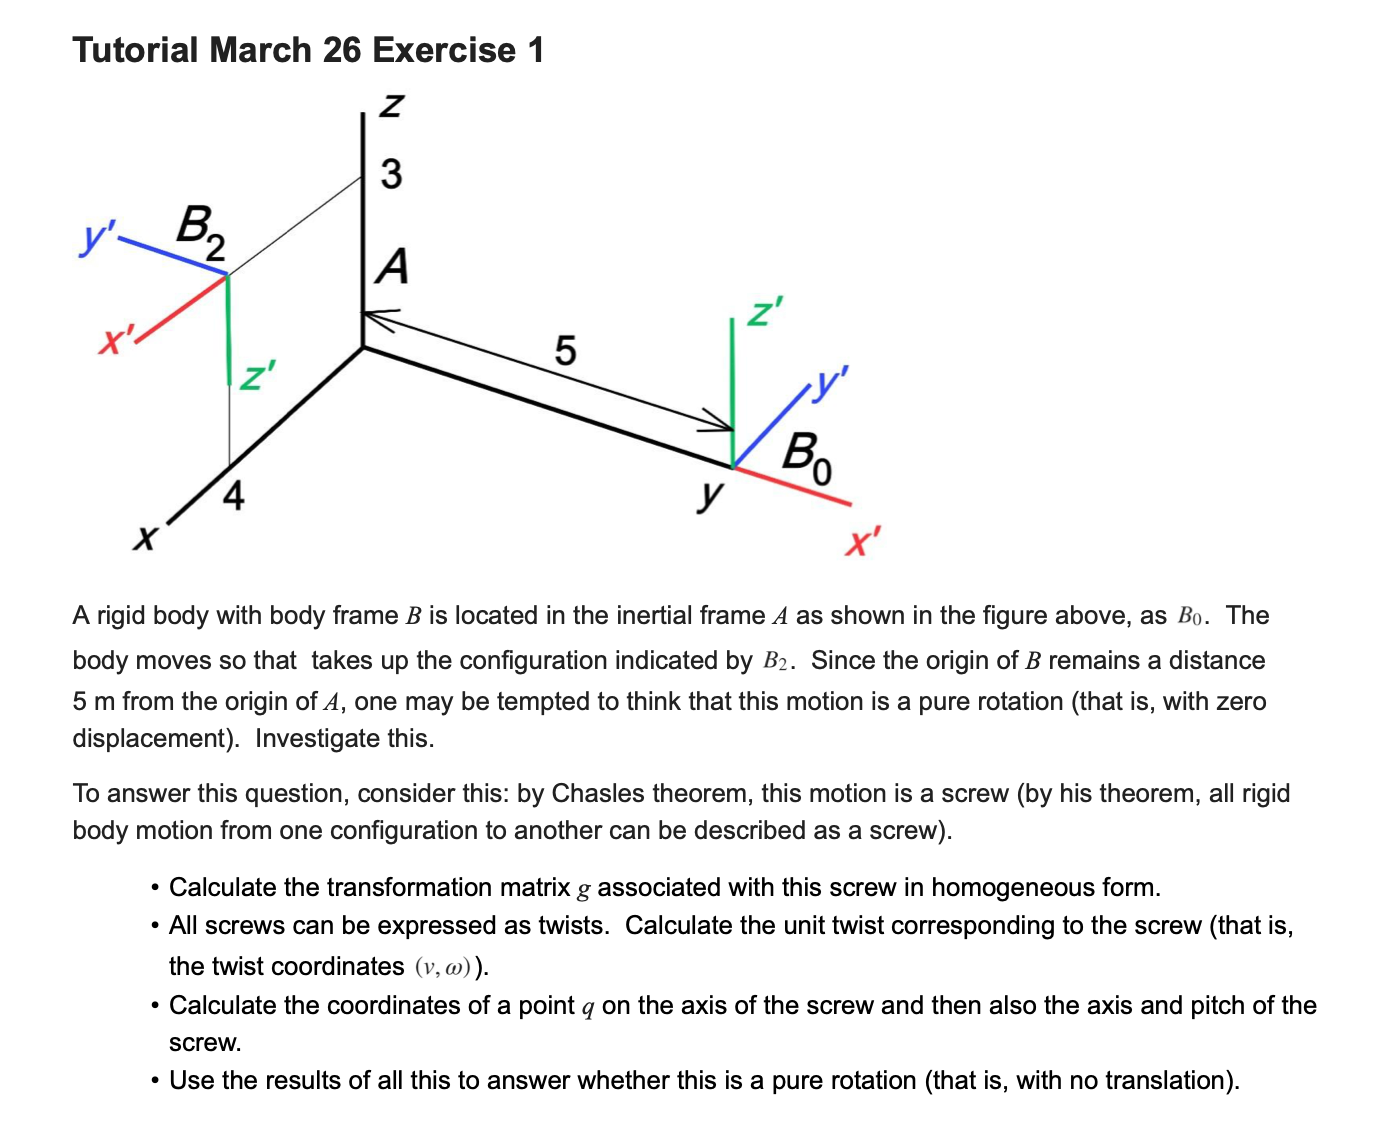

close all; clc; clear
import robo.*

theta90 = deg2rad(-90);
theta180 = deg2rad(180);

- Exercise 1 question 1: list the components of the twist coordinate array (v,xi)

- Calculate the transformation matrix g associated with this screw in homogeneous form.

%先用 homo transfermation表示出来
function Rz = Rz(theta)
Rz = [cos(theta) -sin(theta) 0;
    sin(theta) cos(theta) 0;
    0 0 1];
end

%注意！ 旋转矩阵都是默认执行先移动再旋转，别夏jb搞
%body frame就是向右乘那个选钻矩阵一步一步来，spatial frame就是左乘
%题目里面要的是spatial frame所以是 spatial frame 一定是 算子在左

T0 = [0 -1 0 0;
    1 0 0 5;
    0 0 1 0; 

T0 =      0    -1     0     0
     1     0     0     5
     0     0     1     0
     0     0     0     1


    0 0 0 1]

T01 = [Rz(theta90) [0;0;0];
    zeros(1,3) 1];

Rx21 = [1 0 0;
    0 cos(theta180) -sin(theta180);

Rx21 =     1.0000         0         0
         0   -1.0000   -0.0000
         0    0.0000   -1.0000


    0 sin(theta180) cos(theta180) ]

T12 = [Rx21 [4;-5;3];

T12 =     1.0000         0         0    4.0000
         0   -1.0000   -0.0000   -5.0000
         0    0.0000   -1.0000    3.0000
         0         0         0    1.0000


    zeros(1,3) 1]


T02 =     1.0000    0.0000    0.0000    4.0000
    0.0000   -1.0000   -0.0000         0
         0    0.0000   -1.0000    3.0000
         0         0         0    1.0000


T02 = T0 * T01 *T12


G =    -0.0000    1.0000    0.0000   -1.0000
    1.0000    0.0000   -0.0000   -0.0000
   -0.0000         0   -1.0000    3.0000
         0         0         0    1.0000


G = T02/T0 %相当于 T02 * T0^-1 因为 T02是终极spatial坐标 = G * T0


- All screws can be expressed as twists. Calculate the unit twist corresponding to the screw (that is,the twist coordinates ).

%接下来提取omega，还有v，calc v, using MLS eqn. (2.38)




axang = rotm2axang(G(1:3,1:3));

omega = axang(1:3)' %注意omega一定要是列向量！！

omega =    -0.7071
   -0.7071
    0.0000


theta = axang(4)

theta = 3.1416


omega_h = hatm(omega)

omega_h =          0   -0.0000   -0.7071
    0.0000         0    0.7071
    0.7071   -0.7071         0


%rodrigues 只能输入omega，不是omegahat

shouldbezero3times3 = rodrigues(omega,theta) - G(1:3,1:3)

shouldbezero3times3 = 1.0e-15 *

   -0.3829         0   -0.1478
         0    0.3829    0.1478
    0.1478   -0.1478         0



A = (eye(3) - rodrigues(omega,theta))*omega_h + omega*omega'*theta

A =     1.5708    1.5708   -1.4142
    1.5708    1.5708    1.4142
    1.4142   -1.4142    0.0000



v = A \ G(1:3,4) %这个索引的意思是，1到3个数，第四列的

v =     0.9015
   -1.2198
    0.3536


%下一步组装一个twist 叫做xi = [v,w]
xi = [v ; omega]

xi =     0.9015
   -1.2198
    0.3536
   -0.7071
   -0.7071
    0.0000


- Calculate the coordinates of a point q on the axis of the screw and then also the axis and pitch of the screw.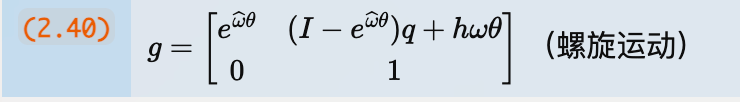

- 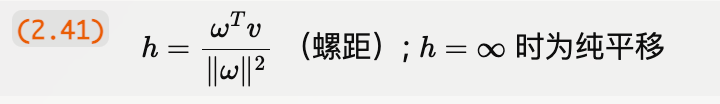

q = omega_h * v

q =    -0.2500
    0.2500
    1.5000


h = omega'* v / norm(omega)^2

h = 0.2251

%上面就是全部答案了，下面是证明一下twist 是否可以表示 G，就是spatial operator

xi_h = wedge(xi) %wedge 函数的作用是把6*1 的twist还原成4x4


xi_h =          0   -0.0000   -0.7071    0.9015
    0.0000         0    0.7071   -1.2198
    0.7071   -0.7071         0    0.3536
         0         0         0         0


xi_hat_scaled = xi_h * theta


xi_hat_scaled =          0   -0.0000   -2.2214    2.8322
    0.0000         0    2.2214   -3.8322
    2.2214   -2.2214         0    1.1107
         0         0         0         0


G_expm = expm(xi_hat_scaled)


G_expm =    -0.0000    1.0000   -0.0000   -1.0000
    1.0000    0.0000    0.0000   -0.0000
         0   -0.0000   -1.0000    3.0000
         0         0         0    1.0000


shouldbezero4 = G_expm - G


shouldbezero4 = 1.0e-14 *

   -0.0383         0   -0.0085   -0.0666
         0    0.0383    0.0370   -0.1176
    0.0122   -0.0166         0   -0.0444
         0         0         0         0
